Preparation

clear

Paramater Settings

MinValue = 10*10^9 ;
ValueSurgeThresholdX = 1.5;
MomContDays = 10 ;
LowLiquidDays = 20 ;
LowLiquidThreshold = 1*10^5 ;
LiquidSurgThreshold = 1.5 ;
LiquidSurgAvgLeadDays = 5 ;
LiquidSurgAvgLagDays = 200 ;
MomMainDays = 30 ;
MomMainRetThreshold = 30/100 ; 
PostSignalBufferDays = 8 ;
StopLossLookbackWindSz = 20;
StopLossThreshold = 8/100 ;

Read data  

PriceTT =  readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Price Data");
VolumeTT = readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Volume Data");
IndexTT = readtimetable ("Trend Trading Input Output Data.xlsx", "Sheet","Index Data");

Data cleaning

PriceTT = fillmissing (PriceTT, "previous");
VolumeTT = fillmissing (VolumeTT, "previous");
IndexTT = fillmissing (IndexTT, "previous");

Sort Symbols Alphabetically 

SymList =  PriceTT.Properties.VariableNames;
SymList = sort (SymList);
uniq = unique (SymList);
SymList (:,end);

PriceTT = PriceTT (:, SymList);
VolumeTT = VolumeTT (:,SymList);

Transaction Value

PriceTT ;
ValueTT = PriceTT ;
ValueTT.Variables = PriceTT.Variables .* VolumeTT.Variables ;


Liquidity constraints

LiquiditySignal = PriceTT ;
ValueVar = ValueTT.Variables ; 
Signal = ValueVar > MinValue ;
Signal (isnan(Signal)) = 0;
LiquiditySignal.Variables = Signal ;
LiquiditySignal ;

clear ValueVar Signal 

Momentum continuation constraints

MomContSignal = PriceTT ;
Price = PriceTT.Variables ;
MomContSignalVar    = MomContSignal.Variables; 

MomContSignalVar (MomContDays:end, :) ;
Price (MomContDays:end, :) ;
Price (1:end-MomContDays, :) ;
MomContSignalVar (MomContDays:end, :) = Price (MomContDays:end, :) ./ Price (1:end-MomContDays+1, :) - 1 ;
MomContSignalVar (1:MomContDays -1, :) = 0 ;
MomContSignalVar (isnan (MomContSignalVar)) = 0;
MomContSignal.Variables = MomContSignalVar;

% MomContSignalVar :

% MomContSignal :

%plot(MomContSignal.Time, MomContSignal.BBCA);

clear MomContSignalVar Price

Avoid inconsistent volume in LowLiquidDays period

LowLiquidSignal = ValueTT ;
LowLiquidSignal.Variables = movmin (ValueTT.Variables, [LowLiquidDays 0]) ;
LowLiquidSignalVar = LowLiquidSignal.Variables ;

LowLiquidSignal.Variables = LowLiquidSignalVar >LowLiquidThreshold ;

% ValueTT
LowLiquidSignal;

%LowLiquidSignalVar < low

% plot (LowLiquidSignal.Time, LowLiquidSignal.ACES)
clear LowLiquidSignalVar 

Liquidity surge detector

LiquidSurgeSignal = ValueTT ;
LiquidSurgeSignalVar = LiquidSurgeSignal.Variables ;
LiquidSurgeSignalAvgLead = movmean (LiquidSurgeSignalVar, LiquidSurgAvgLeadDays,1) ;
LiquidSurgeSignalAvgLag = movmean (LiquidSurgeSignalVar, LiquidSurgAvgLagDays,1) ;
LiquidSurgeSignalX = LiquidSurgeSignalAvgLead ./LiquidSurgeSignalAvgLag ;
LiquidSurgeSignalVar = LiquidSurgeSignalX >LiquidSurgThreshold ;
LiquidSurgeSignalVar (1:LiquidSurgAvgLagDays-1, :) = 0 ;

% SymList (9) ;
LiquidSurgeSignal.Variables = LiquidSurgeSignalVar ;

clear LiquidSurgeSignalVar LiquidSurgeSignalAvgLead LiquidSurgeSignalAvgLag LiquidSurgeSignalX LiquidSurgeSignalVar 

Main Momentum detector

MomSignal = PriceTT ;
Price = PriceTT.Variables ;
MomSignalVar = MomSignal.Variables ;
Price (MomMainDays:end, :) ;
Price (1:end-MomMainDays+1,:) ;
MomSignalRet = Price (MomMainDays:end, :) ./ Price (1:end-MomMainDays+1,:) -1  ;
MomSignalVar (1:MomMainDays-1, :) = 0;
MomSignalVar (MomMainDays:end, :) = MomSignalRet > MomMainRetThreshold ;
 
MomSignal.Variables = MomSignalVar ;

clear MomSignalVar Price MomSignalRet 

Momentum Value Combined Signal

MomValueCombinedSignal = PriceTT ;
MomValueCombinedSignalVar = LiquidSurgeSignal.Variables  .* MomSignal.Variables .* MomContSignal.Variables ;
MomValueCombinedSignal.Variables  = MomValueCombinedSignalVar ;
MomValueCombinedSignal ;

clear MomValueCombinedSignalVar 

Post signal buffer (Zigsaw stabilizer)

PostSignalBufferDays ;
PostSignBuffer = PriceTT ;
PostSignalBufferVar = movmax (MomValueCombinedSignal.Variables, [PostSignalBufferDays 0], 1) ;

PostSignBuffer.Variables = PostSignalBufferVar ;
PostSignBuffer ;

% plot (PostSignalBuffer.Time, PostSignBuffer.ANTM)

clear PostSignalBufferVar 

Stop-Loss Signal

StopLossLookbackWindSz;
StopLossSignal = PriceTT ;
Price = PriceTT.Variables ;
StopLossRetMaxPrice = Price ./ movmax (Price, [StopLossLookbackWindSz, 0], 1) -1   ;
StopLossSignalVar = StopLossRetMaxPrice > - StopLossThreshold ;
StopLossSignal.Variables = StopLossSignalVar ;

% plot (StopLossSignal.Time, StopLossSignal.ARTO)
% a = PriceTT;
% a.Variables = movmax (Price, [StopLossLookbackWindSz, 0], 1);
% plot (a.Time, a.ARTO)

clear StopLossSignalVar StopLossRetMaxPrice Price

Final Combined Signal

FinalCombSignal = PriceTT ;
FinalCombSignalVar = LiquiditySignal.Variables .* LowLiquidSignal.Variables ...
     .* PostSignBuffer.Variables .* StopLossSignal.Variables ;

FinalCombSignal.Variables = FinalCombSignalVar

FinalCombSignal = 2859×665 timetable
       Time        AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    <s

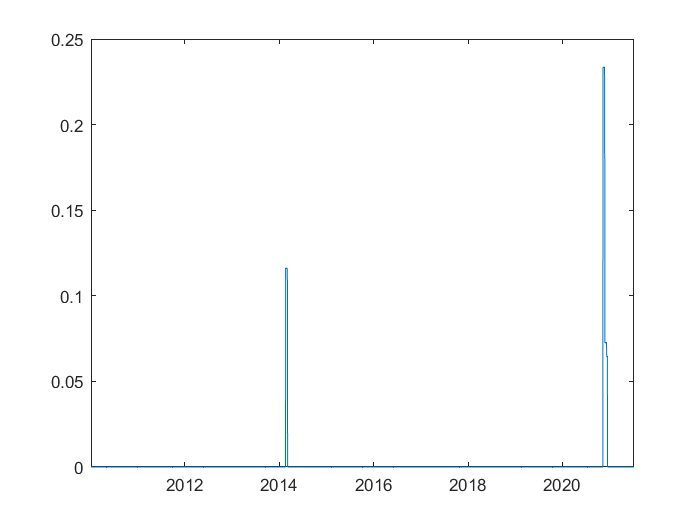

ans =     0.1747    1.4675         0         0    0.2101    0.5163    0.6121    0.6000         0    1.9756    0.3521         0    1.0688    0.9114         0         0         0    0.5493    0.3654         0    0.2947         0    0.6832         0         0    0.3009    0.7941         0    0.9384         0         0         0    0.3681    0.3600         0    0.6434         0    0.7000         0    0.7826    0.5044         0         0         0    0.2500         0    1.6939    1.1561         0         0



plot (FinalCombSignal.Time, FinalCombSignal.BBRI)

max (max(LiquiditySignal.Variables)) 

ans = 1

max (max(LowLiquidSignal.Variables)) 

ans = 1

max (max(StopLossSignal.Variables))
max (max(PostSignBuffer.Variables))

ans = 7.6667

ans = 1

max (max(MomValueCombinedSignal.Variables))

ans = 7.6667

max (max(LiquidSurgeSignal.Variables))
max (max(MomSignal.Variables))
max (max(MomContSignal.Variables))

Leverage

Trading costs

Capital allocation

Daily return

Performance analysis